%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ACTSlab - Sapienza Universita di Roma
% Author: 2024 Camille LANFREDI 

% Description : 
% This MATLAB script reads and processes Channel Impulse Response (CIR) data from specified files.
% It calculates phase metrics such as variance and standard deviation for each CIR. The user is 
% prompted to enter the number of CIRs to display, and the script then visualizes the phase metrics 
% and ratios of negative phases for the specified number of CIRs. The results are plotted and 
% analyzed for each file, providing insights into the phase characteristics of the CIR data.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Read files and extract data
file_paths = {'location(5,3)responder1.txt'};
all_CIR_real_all = {};
all_CIR_imag_all = {};

% Loop to read CIR values from each file
for i = 1:length(file_paths)
    file_path = file_paths{i};
    [CIR_real_all, CIR_imag_all] = readCIRValuesFromMeasurments(file_path);
    all_CIR_real_all{i} = CIR_real_all;
    all_CIR_imag_all{i} = CIR_imag_all;
    disp(['Total number of read CIR pairs for ', file_path, ': ', num2str(length(CIR_real_all))]);
end

Total number of read CIR pairs for location(5,3)responder1.txt: 984


disp(['==========================================================================']);               

CIR number 1 for location(5,3)responder1.txt


Phase variance: 2.3688
Phase standard deviation: 1.5391


CIR number 2 for location(5,3)responder1.txt


Phase variance: 2.1372
Phase standard deviation: 1.4619


CIR number 3 for location(5,3)responder1.txt


Phase variance: 2.5457
Phase standard deviation: 1.5955


CIR number 4 for location(5,3)responder1.txt


Phase variance: 2.3481
Phase standard deviation: 1.5323


CIR number 5 for location(5,3)responder1.txt


Phase variance: 2.2019
Phase standard deviation: 1.4839


CIR number 6 for location(5,3)responder1.txt


Phase variance: 1.8521
Phase standard deviation: 1.3609


CIR number 7 for location(5,3)responder1.txt


Phase variance: 4.2174
Phase standard deviation: 2.0536


CIR number 8 for location(5,3)responder1.txt


Phase variance: 4.848
Phase standard deviation: 2.2018


CIR number 9 for location(5,3)responder1.txt


Phase variance: 3.1709
Phase standard deviation: 1.7807


CIR number 10 for location(5,3)responder1.txt


Phase variance: 4.2174
Phase standard deviation: 2.0536


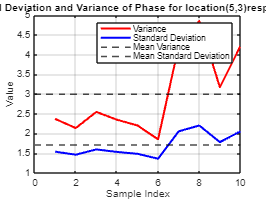


% Initialize vectors for negative phase ratios, variances, and standard deviations
negative_phase_ratios = cell(1, length(file_paths));
varPhase = cell(1, length(file_paths));
stdPhase = cell(1, length(file_paths));

while true
    % Prompt the user for the number of CIRs to display
    prompt = 'Enter the number of CIRs you want to display or 0 to exit: ';
    numCIRs = input(prompt);

    if numCIRs == 0 % Exit if 0 is entered
        break;
    end

    if numCIRs > length(all_CIR_real_all{1})
        disp('The number entered exceeds the available CIR pairs. Please enter a valid number.');
        continue;
    end

    % Process and analyze the CIRs
    for CIRNumber = 1:numCIRs
        for i = 1:length(file_paths)
            file_path = file_paths{i};
            CIR_real_all = all_CIR_real_all{i};
            CIR_imag_all = all_CIR_imag_all{i};

            if CIRNumber > 0 && CIRNumber <= length(CIR_real_all)
                disp(['CIR number ', num2str(CIRNumber), ' for ', file_path]);
                disp(['==========================================================================']);               

                % Extract real and imaginary values
                CIR_real = CIR_real_all{CIRNumber}';
                CIR_imag = CIR_imag_all{CIRNumber}';
                
                % Calculate phase metrics
                [CIR_magnitude, CIR_phase, std_devs2, var_phase] = calculatePhaseMetrics(CIR_real, CIR_imag);
                
                % % Display CIR magnitude
                % figure;
                % stem(CIR_magnitude(721:end));
                % title(['CIR Magnitude - ', file_path]);
                % xlabel('Samples');
                % ylabel('Magnitude');
                % grid on;
                
                % Visualize results
                [ratio_negative_phases, phaseVar, phaseSTD] = visualizeResults(CIR_phase, std_devs2, var_phase, CIRNumber, CIR_magnitude, CIR_phase, file_path);

                % Store results in respective vectors
                negative_phase_ratios{i}(CIRNumber) = ratio_negative_phases;
                varPhase{i}{CIRNumber} = phaseVar;
                stdPhase{i}{CIRNumber} = phaseSTD;
            end
            disp('==========================================================================');
        end
    end

    % Convert cell arrays to matrices for plotting
    for i = 1:length(file_paths)
        varPhase_matrix = cell2mat(varPhase{i});
        stdPhase_matrix = cell2mat(stdPhase{i});

        meanVar = mean(varPhase_matrix);
        meanSTD = mean(stdPhase_matrix);
        
        % Plot the data for each file
        figure;
        plot(varPhase_matrix, 'r', 'LineWidth', 2);
        hold on;
        plot(stdPhase_matrix, 'b', 'LineWidth', 2);
        yline(meanVar, 'black--', 'LineWidth', 1.5);
        yline(meanSTD, 'black--', 'LineWidth', 1.5);
        hold off;
        title(['Standard Deviation and Variance of Phase for ', file_paths{i}]);
        xlabel('Sample Index');
        ylabel('Value');
        legend('Variance', 'Standard Deviation', 'Mean Variance', 'Mean Standard Deviation');
        grid on;
    end
end


% Function Definitions

function [CIR_magnitude, CIR_phase, std_devs2, var_phase] = calculatePhaseMetrics(CIR_real, CIR_imag)
    % Calculate magnitude and phase
    CIR_magnitude = sqrt(CIR_real.^2 + CIR_imag.^2);
    CIR_phase = angle(CIR_real(721:end) + 1i * CIR_imag(721:end));

    % Calculate standard deviations and variances for 720-sample windows
    numSamples = length(CIR_real);
    std_devs2 = zeros(1, numSamples - 719);
    var_phase = zeros(1, numSamples - 719);
    for i = 1:(numSamples - 719)
        CIR_imag_window = CIR_imag(i:i+719);
        CIR_real_window = CIR_real(i:i+719);
        phi_rad2 = atan2(CIR_imag_window, CIR_real_window);
        phi_deg2 = rad2deg(phi_rad2);
        var_phase(i) = var(phi_deg2);
        std_devs2(i) = std(phi_deg2);
    end
end

function analyzeSpectrum(signal)
    % Use Fourier transform to analyze the spectrum
    % [psd, freq] = periodogram(signal);
    % figure;
    % plot(freq, 10*log10(psd));
    % xlabel('Frequency (Hz)');
    % % ylabel('Power Spectral Density (dB/Hz)');
    % title('Filtered Signal Spectrum');
end

function displayMetrics(CIR_phase)
    % Calculate and display phase metrics
    % variance_phase = var(CIR_phase);
    % std_phase = std(CIR_phase);
    % kurtosis_phase = kurtosis(CIR_phase);
    % skewness_phase = skewness(CIR_phase);
    
    % Calculate group delay and its standard deviation
    unwrapped_phase = unwrap(CIR_phase);
    group_delay = diff(unwrapped_phase);
    if length(group_delay) < 2
        group_delay_std_dev = NaN;
    else
        group_delay_std_dev = std(group_delay);
    end

    % fprintf('Phase variance: %f\n', variance_phase);
    % fprintf('Phase standard deviation: %f\n', std_phase);
    % fprintf('Phase kurtosis: %f\n', kurtosis_phase);
    % fprintf('Phase skewness: %f\n', skewness_phase);
    % fprintf('Group delay standard deviation: %f\n', group_delay_std_dev);
end

function [ratio_negative_phases, phaseVar, phaseSTD] = visualizeResults(CIR_phase, std_devs2, var_phase, CIRNumber, CIR_magnitude, CIR_phase_angles, file_path)
    % Calculate the ratio of negative phases
    num_negative_phases = sum(CIR_phase < 0);
    num_positive_phases = sum(CIR_phase > 0);

    phaseVar = var(CIR_phase);
    disp(['Phase variance: ', num2str(phaseVar)]);
      
    phaseSTD = std(CIR_phase);
    disp(['Phase standard deviation: ', num2str(phaseSTD)]);
    
    total_phases = length(CIR_phase);
    ratio_negative_phases = num_negative_phases / total_phases;
    
    % % Visualize phase
    % figure;
    % stem(rad2deg(CIR_phase));
    % xlabel('CIR number');
    % ylabel('Phase (Degrees)');
    % title(['Phase - CIR ', num2str(CIRNumber), ' ', file_path, ' - Ratio of Negative Phases: ', num2str(ratio_negative_phases)]);
    % axis([0 400 -180 180]);  
end
